dataPath = 'acc\';        % 路径
dataDir = dir([dataPath '*.txt']); 

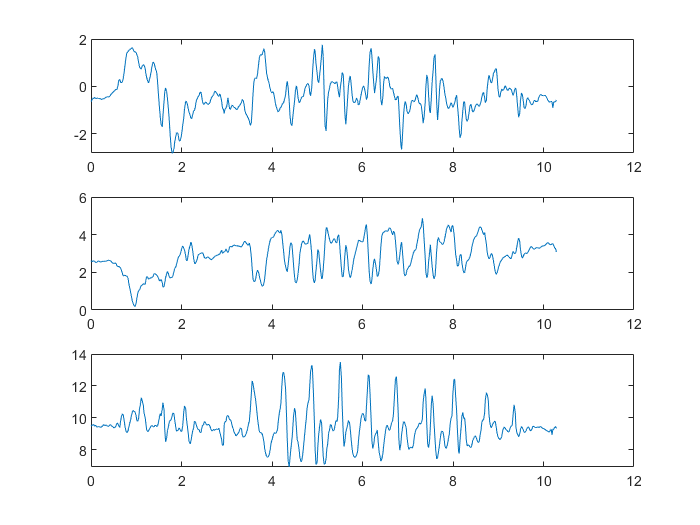

data = importdata([dataPath dataDir(2).name]);
base_time = data(1,4);
t = 0.001*(data(:,4)' - base_time);
ax = data(:,1)';
ay = data(:,2)';
az = data(:,3)';




figure(1)
subplot(3,1,1);
plot(t, ax);
subplot(3,1,2);
plot(t, ay);
subplot(3,1,3);
plot(t, az);

a = ax.*ax + ay.*ay + az.*az

a =    97.0360   97.5561   98.1746   98.8381   96.6498   97.6257   96.4788   95.3412   96.5974   95.7461   95.7468   95.1780   96.2238   96.6714   98.7013   97.6311   97.6636   98.2498   97.0960   96.8704   96.9095   98.5533   98.3576   96.3560   95.9829   94.6458   93.9110   95.1924   96.3674   98.7436   98.4266   95.4397   93.4910  101.0711  105.9572  108.8076  106.8558  100.0091   92.8106   88.9243   87.3951   89.2709   92.7166   97.0019  100.1697  106.0414  110.5583  111.9708  110.4547  109.3231


a = power(a, 0.5)

a =     9.8507    9.8770    9.9083    9.9417    9.8311    9.8806    9.8224    9.7643    9.8284    9.7850    9.7850    9.7559    9.8094    9.8322    9.9349    9.8808    9.8825    9.9121    9.8537    9.8423    9.8443    9.9274    9.9175    9.8161    9.7971    9.7286    9.6908    9.7567    9.8167    9.9370    9.9210    9.7693    9.6691   10.0534   10.2936   10.4311   10.3371   10.0005    9.6338    9.4300    9.3485    9.4483    9.6289    9.8490   10.0085   10.2976   10.5147   10.5816   10.5097   10.4558


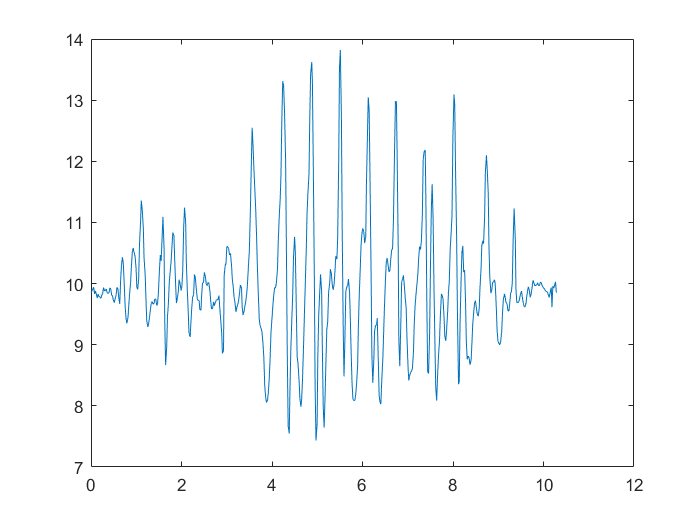

figure(2)
plot(t,a)